ans = 192×192 uint8 matrix
   169   165   174   179   172   172   172   171   170   169   167   166   170   170   162   159   168   168   176   172   173   175   172   173   173   175   173   174   171   172   172   173   175   175   176   174   171   168   169   173   183   182   179   178   176   174   176   168   172   167
   170   171   171   174   182   178   174   174   171   170   170   169   168   167   164   173   168   172   179   170   170   173   172   170   172   177   175   176   176   174   170   176   171   177   174   182   170   175   172   181   173   179   180   173   175   177   174   173   171   171
   172   171   179   171   177   177   176   178   170   170   169   173   169   166   166   171   180   186   179   173   178   175   168   168   168   174   171   175   175   175   171   172   177   177   177   174   176   172   175   179   178   177   180   180   175   178   174   179   174   168
   169   163   187   174   172   173   171   176   179   173   170   1

ans = 192×192 uint8 matrix
   147   152   153   152   151   153   152   156   151   152   152   153   149   150   154   154   153   159   158   158   154   156   154   154   154   146   144   143   133   131   141   147   134   133   139   147   151   154   152   150   152   149   147   147   149   151   154   155   159   159
   153   149   151   153   150   158   159   154   156   158   152   151   153   153   153   153   152   159   159   156   153   157   153   155   152   148   145   146   138   131   144   144   132   134   143   145   151   157   157   158   150   153   148   149   151   151   157   155   159   158
   148   149   158   155   154   162   164   160   162   160   155   155   155   156   155   155   153   158   157   156   157   156   158   156   155   151   148   152   147   137   132   149   139   133   137   149   156   161   157   158   148   152   150   150   154   154   161   154   160   161
   155   150   153   156   158   161   162   166   162   164   159   1

ans = 192×192 uint8 matrix
   174   173   174   174   175   181   176   173   172   172   173   175   171   175   178   181   180   176   173   174   177   178   177   178   181   180   179   179   179   177   176   178   176   178   180   177   178   180   180   177   185   180   180   173   172   171   175   180   180   180
   175   175   176   176   176   179   180   174   177   175   176   175   171   175   179   178   178   176   175   177   181   182   182   176   179   180   181   181   179   176   176   180   178   180   183   180   181   182   181   184   184   184   180   178   170   172   177   187   183   181
   175   176   179   179   179   179   178   174   177   181   180   175   175   181   180   182   179   179   181   178   181   183   183   180   181   181   184   184   180   178   180   179   182   179   181   181   181   183   185   182   183   181   179   178   172   179   184   183   186   183
   176   178   176   182   185   179   177   175   179   176   178   1

ans = 192×192 uint8 matrix
   165   166   167   170   172   172   175   170   171   171   165   167   166   164   170   178   180   179   173   173   172   173   169   170   172   172   173   175   174   175   177   176   178   178   177   178   175   173   173   177   177   176   175   174   172   183   169   165   165   175
   172   168   167   171   170   170   174   171   170   167   163   169   169   164   168   177   181   177   173   172   172   173   172   172   173   174   174   175   176   177   179   177   176   178   178   179   173   172   175   180   180   177   184   178   177   173   180   170   166   170
   172   170   170   170   168   169   174   173   171   165   164   171   167   162   164   173   180   176   173   172   171   173   175   174   174   172   174   175   175   180   176   178   174   175   176   175   176   178   175   178   178   176   185   181   178   173   175   169   170   179
   171   170   170   172   173   170   173   173   169   165   168   1

ans = 192×192 uint8 matrix
   141   155   153   149   147   151   156   150   146   148   148   145   144   145   147   155   153   153   156   153   155   156   151   150   152   155   150   151   140   128   128   135   146   147   147   150   141   141   149   153   150   146   149   146   148   145   146   145   147   154
   152   151   157   152   152   155   153   149   149   148   144   147   151   146   153   145   155   148   159   155   156   157   156   155   156   154   145   150   141   130   138   143   149   152   152   151   145   138   143   148   148   149   145   151   147   147   149   157   149   158
   159   152   157   151   158   158   158   157   154   152   152   151   152   154   153   149   151   149   159   159   150   152   150   160   154   158   152   150   147   135   131   136   141   144   146   149   133   138   146   151   144   153   155   161   152   157   150   153   156   159
   153   160   150   157   156   156   153   156   161   154   148   1

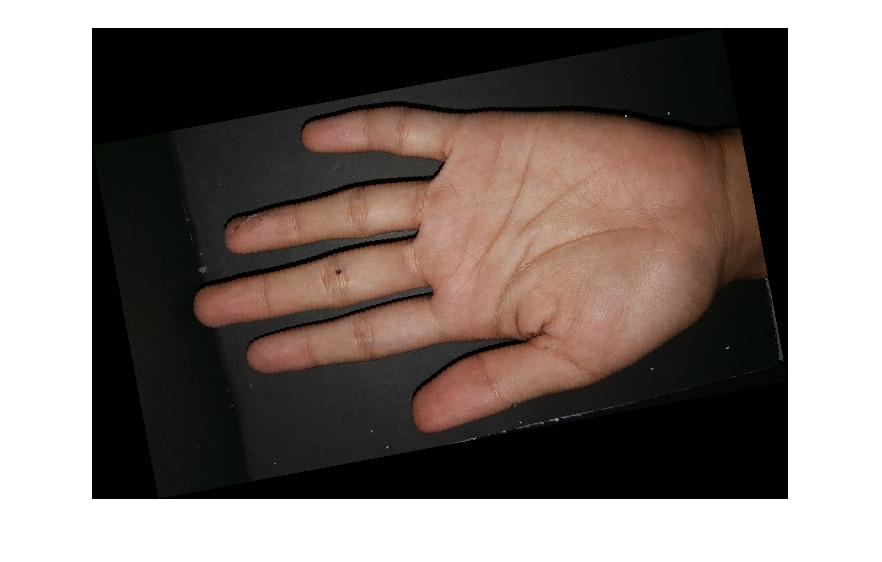

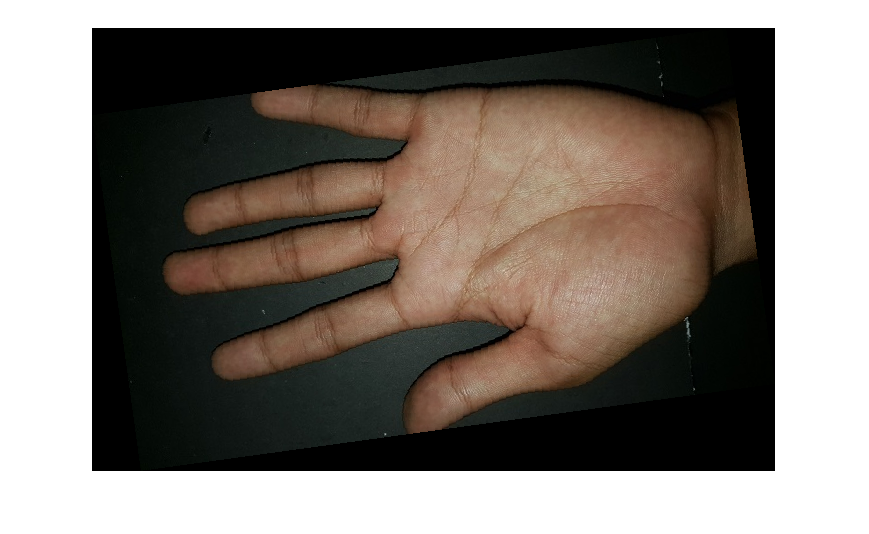

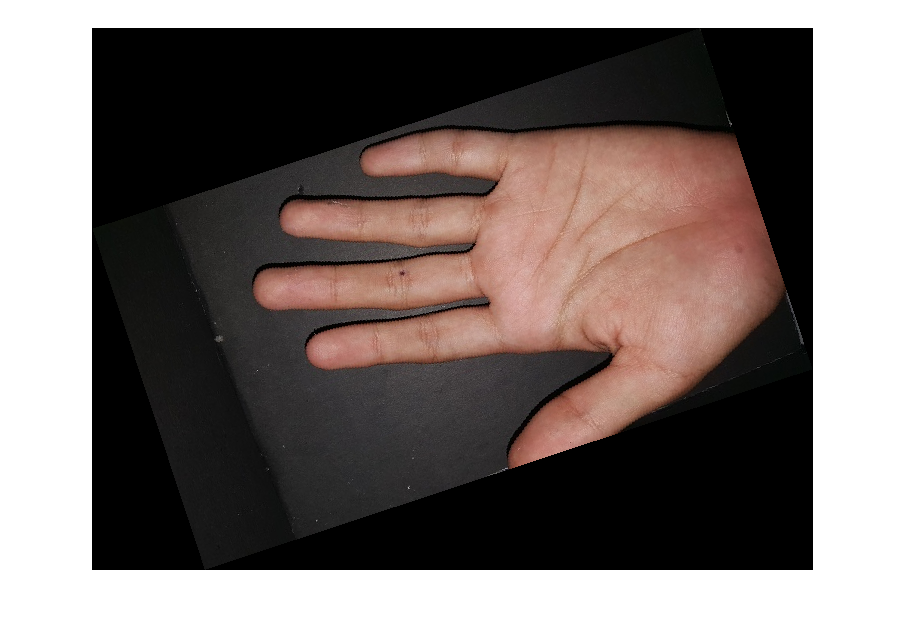

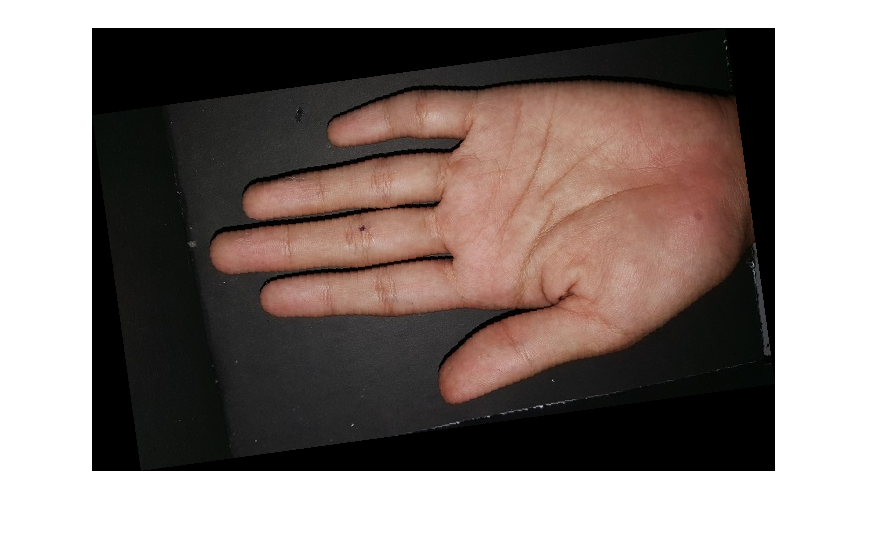

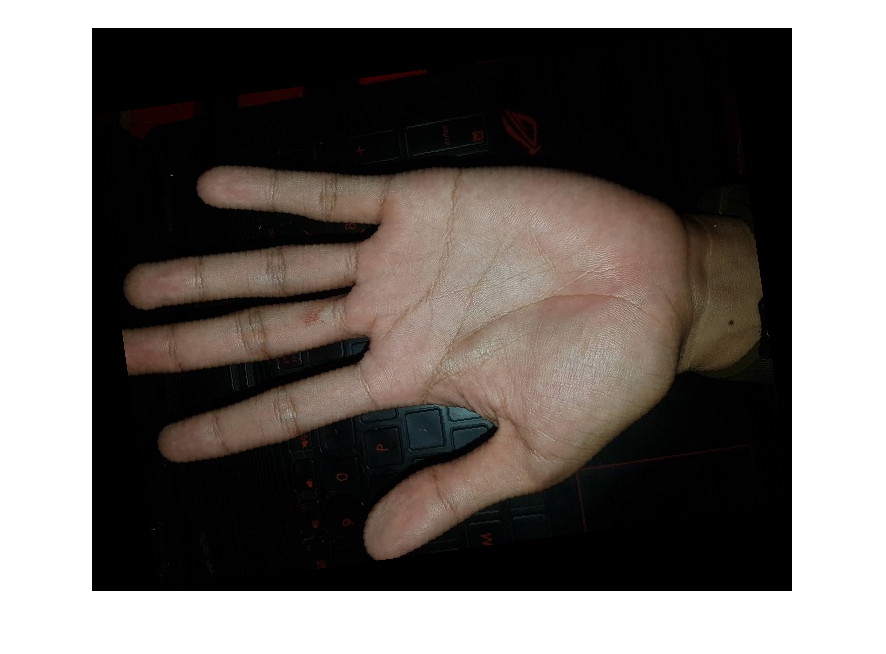

clear;
img_path='Samples/0001';
addpath(img_path);
addpath('Functions/DetectROI');
addpath('Functions/Gabor');
ROIL=repmat(struct('image',uint8(zeros(192,192))),1,5);
OB=repmat(struct('image',uint8(zeros(192,192))),1,5);
GABORL=repmat(struct('image',uint8(zeros(192,192))),1,5);
for i=1:5
    ROIL(i).image=findROI(img_path, ['/0001_m_l_0' num2str(i) '.jpg'],192,150);
    
    ROIL(i).image
    ROIL(i).image = uint8(255*mat2gray(ROIL(i).image));
    ROIL(i).image = medfilt2(ROIL(i).image,[9 9]);
end

## cari ROI

figure;
suptitle('ROI - Tangan Kiri');
for j=1:5
    subplot(2,3,j)
    imshow(ROIL(j).image);
    title(['Citra 0' num2str(j) '.jpg']);
end

## Deteksi Tepi

figure;
suptitle('Hasil Deteksi Tepi');
h = [ -1  2  -1 
      -1  2  -1
     -1 2 -1 ];
for j=1:5
    subplot(2,3,j)
    ROIL(j).image = imresize(ROIL(j).image, [96 96]);
    ROIL(j).image = filter2(h, ROIL(j).image);
    %imL_bf_filter=edge(ROIL(j).image,'sobel');
    %imL_af_filter=bwmorph(imL_bf_filter,'bridge');
    imshow(ROIL(j).image);
    title(['Citra 0' num2str(j) '.jpg']);
end

figure;
suptitle('Hasil Deteksi Tepi');
fun = @(block_struct) ...
   std2(block_struct.data) * ones(size(block_struct.data));
for j=1:5
    subplot(2,3,j)
    OB(j).image = blockproc(ROIL(j).image,[12 12],fun);
    OB(j).image = imresize(uint8(OB(j).image), [8 8]);
    imshow(OB(j).image);
    OB(j).image = im2double(OB(j).image);
    title(['Citra 0' num2str(j) '.jpg']);
end